mcad=callMCAD
MCADPath=getMCADPathCurrent(mcad)


## UI/UX 고려사항

사용자가 

몇개를 셋팅'해야' 되는지

몇개 셋팅   '했'  는지

몇개 셋팅  '됐'  는지

## 1. Geometry Modeling

## 2.MCAd Lab Setting p.33


mcad.SetMotorLABContext
mcad.ShowMagneticContext
% category2Out      ='_MotorLab'
TabMCADLabSetting =defMcadLabBuildSetting
setMcadTableVariable(TabMCADLabSetting,mcad)
mcad.BuildModel_Lab

% Auto Name
ModelType_MotorLAB                  =        
LossModel_Lab                       =    
MaxModelCurrent_RMS_MotorLAB        =                    
ModelBuildSpeed_MotorLAB            =                


#### setting Tab

% Auto Name
CurrentSpec_MotorLAB      =
tempTable.IM_InitialSlip_MotorLAB   = 0.003
tempTable.IM_SlipRes_MotorLAB       = 1e-6

setMcadVariable(tempTable,mcad)



#### Lab Calc Setting [ALL the above can be Changed]

MCADLabCalcSetTable=defMcadLabCalcSetting()
setMcadTableVariable(MCADLabCalcSetTable,mcad)

MCADTable = readMcadActiveX2Table("D:\KangDH\Emlab_emach\tools\ActiveXParameters.txt")

% MCADTable=defMcadTable();
AutoVarStruct=convertMCADActiveXTable2MCADVarStruct(MCADLabCalcSetTable)
AutoVarStruct.DCBusVoltage=400
AutoVarStruct.ModulationIndex_MotorLAB=0.95
AutoVarStruct.StatorIronLossBuildFactor=1
AutoVarStruct.RotorIronLossBuildFactor =1



%% loss Tab
Windage_Loss=filterMCADTable(MCADTable,'Windage_Loss_@Ref_Speed')
FricTable=filterMCADTable(MCADTable,'Fric')
FricTable=filterMCADTableWithAnyInfo(FricTable,'Watts','Units')
StrayTable=filterMCADTable(MCADTable,'StrayLoadLossCalculationType')
StrayTable=filterMCADTableWithAnyInfo(StrayTable,'Undefined','Units')

## Setting MCAD

MechLossTable=mergeTables(FricTable,StrayTable);
setMcadTableVariable(MechLossTable,mcad);
setMcadVariable(AutoVarStruct,mcad);


## Build Model

mcad.BuildModel_Lab


## [TB]Effi Map

## OP Validation

MCADLAbSimulParaTable =filterMCADTableWithAnyInfo(MCADTable,'Simulation','Category')
MLABVarStruct        =convertMCADActiveXTable2MCADVarStruct(MCADLAbSimulParaTable)
MLABAllVarStruct     =convertMCADActiveXTable2MCADVarStruct(MCADTable)

NewVarStruct.LabMagneticCoupling=1
NewVarStruct.LabThermalCoupling=1
NewVarStruct.OpPointSpec_MotorLAB=0
NewVarStruct.SpeedDemand_MotorLAB=6500
NewVarStruct.TorqueDemand_MotorLAB=100
setMcadVariable(NewVarStruct,mcad)

mcad.CalculateOperatingPoint_Lab
% Emag Context
mcad.ShowMagneticContext
mcad.InitialiseTabNames
mcad.DisplayScreen('Calculation')

MCADMAgTab=filterMCADTableWithAnyInfo(MCADTable,'Magnetics','Category')
filterMCADTable(MCADMAgTab,'SaturationCalc')
% Analytical
IMMagCalc.IMSaturationCalcMethod=0;
IMMagCalc.SupplyDefinition=1;
IMMagCalc.IMMaxRMSCurrent_SaturationCalc =900
setMcadVariable(IMMagCalc,mcad)
% calc IM Saturation 
mcad.CalculateIMSaturationModel()


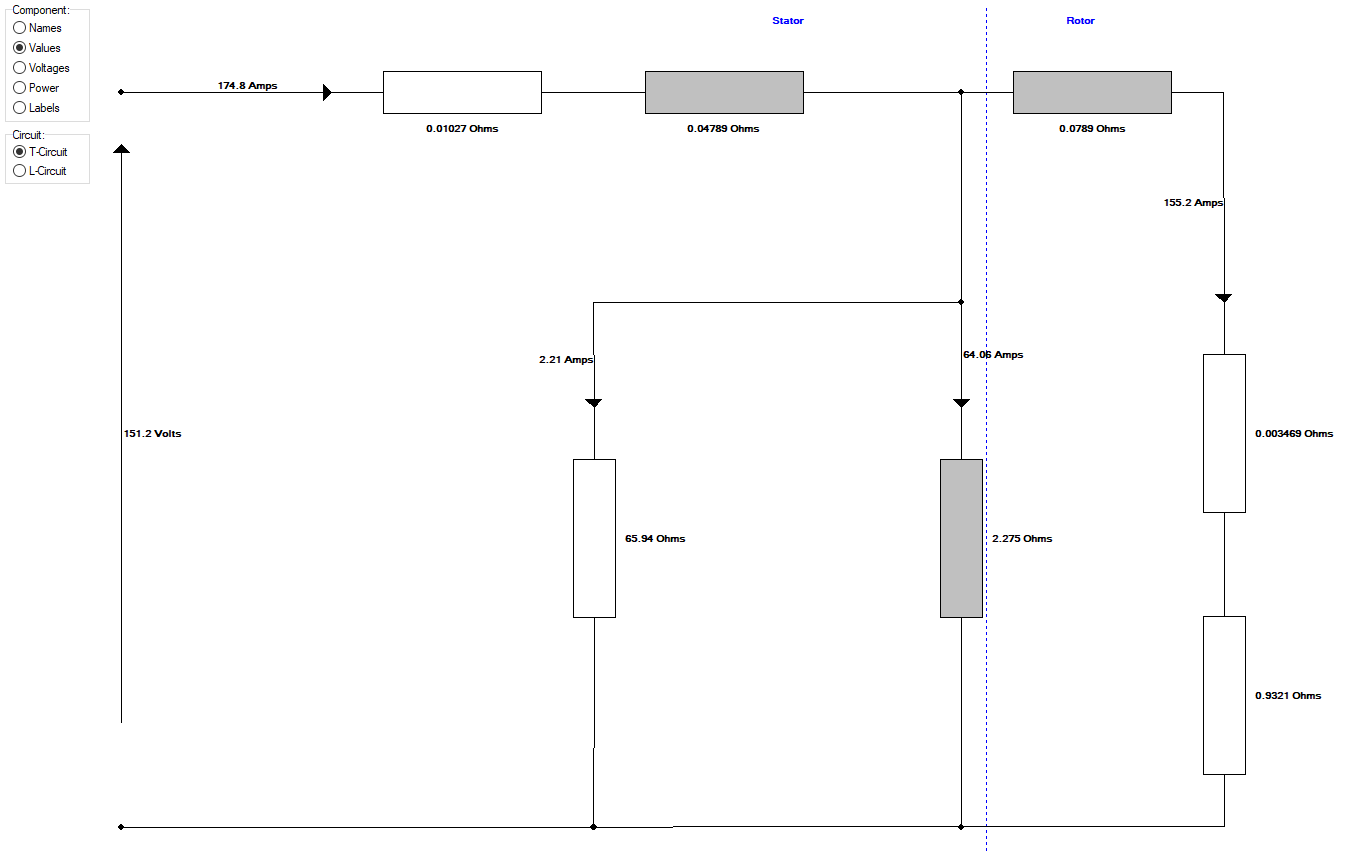

## Saturation Model

### Loop Up table - Magnetizing Inductance Variation

Analytical : non-linear magnetic reluctance method for a half-pole solution domation

FEA : 2D static FEA (solution domain determined by symmetry)

## Performance Test

### MEC

####     Single Load

####     No-load Point

     나머지는 Voltage Driven

### FEM !

####     Single Load

    compare LAB finite-element results

####     Locked Rotor

    leakage inductance and rotor

## Synchronous Speed

    for calibration 

    core losses   : Rc

    Inductance(Self, Mutual) : leakage & magnetizing Inductance


% 
mcad.InitialiseTabNames

mcad.DisplayScreen('Output Data')
mcad.DisplayScreen('Output Data;Lookup')
mcad.DisplayScreen('Output Data;Lookup;Graphs;Saturation Factor')
mcad.DisplayScreen('Output Data;Lookup;Graphs;Iron Losses')



## Settings - InputData


mcad.DisplayScreen('Input Data;Settings;E-magnetics')


### Calculation Setting

#### MEC Cac Setting

mcad.DisplayScreen('Input Data;Settings;Calculation;Analytic')

%1.  EEC Solver
%2.  TN CAlc

%3.   MEC Solver

#### FEA Calc Setting

mcad.DisplayScreen('Input Data;Settings;Calculation;FEA')


